# EXAMPLE TO SHOW PLOTS OF THE PSD AND WRC PREDICTIONS ON DIFFERENT MODELS

## INPUT DATA:

Data record to plot:

% Data input table DATA_INPUT must previously loaded:
load('DATA_ACAP.mat', 'DATA_INPUT');
load('DATA_ACAP.mat', 'ROSETTA_SCCBD');
% Comment: NRECORD = 1 for Fig 13, NRECORD = 420 for fig 18
NRECORD = 1;
DATA = DATA_INPUT;
DATA_RECORD = DATA_INPUT(NRECORD,:);

Input data for Arya and Paris (1981) model:

AP81_alfa = 1.38;
    VG_thres = ROSETTA_SCCBD.th_res(NRECORD);
    VG_thsat = ROSETTA_SCCBD.th_sat(NRECORD);
    VG_alpha = ROSETTA_SCCBD.alpha(NRECORD);
    VG_n = ROSETTA_SCCBD.n(NRECORD);

Input data for ACAP model:

    optionsACAP = struct(...
	'fit_to_log',true,...
	'fit_max_Se',0.95,...
	'fit_min_Se',0.1,...
	'saturation_vs_porosity',1.0,...
	'opt_theta_res',1,...
	'opt_theta_sat',1,...
	'opt_beta',5,... %1:fix, 2:tex, 3:fix_fit,4:fix_emp, 5:emp_dp, 6:fit_dp
	'opt_Dg0',2,...
    'opt_fitMVG',1,...
    'opt_fitRosetta',1);

## CALCULATIONS:

Creation of instances of each soil model: (to construct a soil and calculate all required properties)

soilAP81 = class_soil_AP81(...
    'GSD',DATA_RECORD.GSD{1},...
    'WRC',DATA_RECORD.HT_DRY{1},...
    'npor',DATA_RECORD.NPOR,...
    'alfa',1.38);

soilAP99 = class_soil_AP99(...
    'GSD',DATA_RECORD.GSD{1},...
    'WRC',DATA_RECORD.HT_DRY{1},...
    'npor',DATA_RECORD.NPOR);

soilAP08 = class_soil_AP08(...
    'GSD',DATA_RECORD.GSD{1},...
    'WRC',DATA_RECORD.HT_DRY{1},...
    'npor',DATA_RECORD.NPOR);

soilCNEAP = class_soil_CNEAP(...
    'GSD',DATA_RECORD.GSD{1},...
    'WRC',DATA_RECORD.HT_DRY{1},...
    'npor',DATA_RECORD.NPOR);

soilMohammadi = class_soil_Mohammadi(...
    'GSD',DATA_RECORD.GSD{1},...
    'WRC',DATA_RECORD.HT_DRY{1},...
    'npor',DATA_RECORD.NPOR);

soilRosetta = class_soil_VanGenuchten(...
    'GSD',DATA_RECORD.GSD{1},...
    'WRC',DATA_RECORD.HT_DRY{1},...
    'npor',DATA_RECORD.NPOR, ...
    'thres',VG_thres, ...
    'thsat',VG_thsat, ...
    'alpha',VG_alpha, ...
    'n',VG_n ...
    );

soilACAP = class_soil_ACAP(...
    'GSD',DATA_RECORD.GSD{1},...
    'WRC',DATA_RECORD.HT_DRY{1},...
    'npor',DATA_RECORD.NPOR,...
    'options',optionsACAP);

Instance of class_soil_PLOT: (to plot a soil, built from the soilACAP model, other soils will be added later)

soilplot = class_soil_PLOT(soilACAP);
soilplot = soilplot.show_PSD(strcat('Pore Size Distribution: COD:',int2str(DATA_INPUT.COD(NRECORD))));

Add PSD curves from other soils:

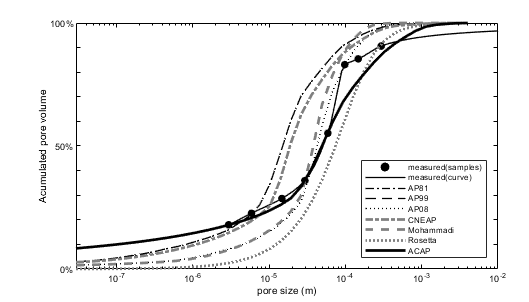

soilplot = soilplot.add_PSD_from_GSD(soilAP81,'-.',1,[0,0,0]);
soilplot = soilplot.add_PSD_from_GSD(soilAP99,'--',1,[0,0,0]);
soilplot = soilplot.add_PSD_from_GSD(soilAP08,':',1,[0,0,0]);
soilplot = soilplot.add_PSD_from_GSD(soilCNEAP,'-.',2,[0.5,0.5,0.5]);
soilplot = soilplot.add_PSD_from_GSD(soilMohammadi,'--',2,[0.5,0.5,0.5]);
soilplot = soilplot.add_PSD_from_GSD(soilRosetta,':',2,[0.5,0.5,0.5]);
soilplot = soilplot.add_PSD_from_GSD(soilACAP,'-',2,[0,0,0]);
legend({'measured(samples)','measured(curve)','AP81','AP99','AP08','CNEAP','Mohammadi','Rosetta','ACAP'},'Location','Southeast');
% With soil NRECORD = 420 for fig 18 :
% saveas(gcf,'.\FIGURES\Fig_18_Predicted WRC vs measured WRC from test 6 in Chiapponi.pdf','pdf');
% saveas(gcf,'.\FIGURES\Fig_18_Predicted WRC vs measured WRC from test 6 in Chiapponi.emf','emf');
% savefig('.\FIGURES\Fig_18_Predicted WRC vs measured WRC from test 6 in Chiapponi.fig');
% With soil record 1:
saveas(gcf,'.\FIGURES\Fig_06_Pore size distribution for UNSODA record 1010.pdf','pdf');
saveas(gcf,'.\FIGURES\Fig_06_Pore size distribution for UNSODA record 1010.emf','emf');
savefig('.\FIGURES\Fig_06_Pore size distribution for UNSODA record 1010.fig');

clear('NRECORD','DATA','DATA_RECORD','AP81_alfa','optionsACAP','soilAP81','soilAP99','soilAP08','soilCNEAP','soilACAP','soilMohammadi','soilRosetta','soilplot');